# Applied Mathematics

## Numerical Linear Algebra

### Dense vs. Sparse Matrices 

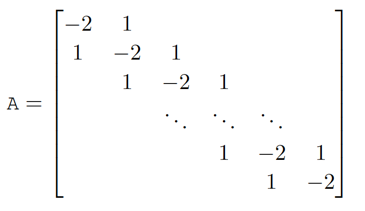

This is a **sparse matrix**, a matrix with relatively small number of nonzero entries, compared to its size.

Let $A\in R^{m\times n}$ be a sparse matrix with $n_z$ nonzeros. Dense storage requires $\textrm{mn}$ entries.

**Sparse matrix storage formats**

Triplet format

- Store nonzero values and corresponding row/column

- Storage required = ${3n}_z$ ($2n_z$ `int`s and $n_z$ `double`s)

- Simplest but most inefficient storage format

- General in that no assumptions are made about sparsity structure

- Used by MATLAB (column-wise)

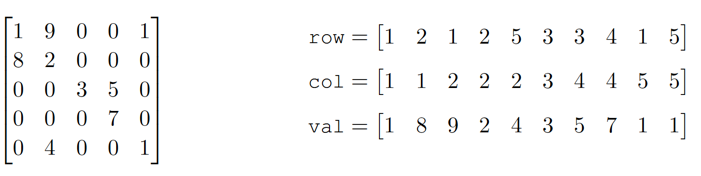

Compressed Sparse Row (CSR) format

- Store nonzero values, corresponding column, and pointer into value array corresponding to first nonzero in each row

- Storage required = $2n_z +m$

Compressed Sparse Column (CSC) format

- Store nonzero values, corresponding row, and pointer into value array corresponding to first nonzero in each column

- Storage required = $2n_z +n$

Diagonal Storage format

- Useful for banded matrices

Skyline Storage format

Block Compressed Sparse Row (BSR) format

#### Break-even point for sparse storage

For $A\in R^{m\times n}$  with $n_z$ nonzeros, there is a value of $n_z$ where sparse vs dense storage is more efficient.

- For the triplet format, the cross-over point is defined by ${3n}_z =\textrm{mn}$, so if $n_z \le \frac{\textrm{mn}}{3}$ use sparse storage, otherwise use dense format.

- Cross-over point depends not only on $m$, $n$, $n_z$ but also on the data types of `row, col, val.`

Besides storage efficiency, data access for linear algebra applications and ability to exploit symmetry in storage is also important.

**Quiz.**

Suppose you have a tridiagonal 1000x1000 matrix. All entries in those three diagonals are non-zero. Calculate how many numbers can we omit if we store it as a triplet instead of a full matrix?

""

ans = ""

It sounds that a tridiagonal matrix is better stored as a triplet. For a tridiagonal `nxn` matrix, find the greatest `n` in which the triplet is not helpful in saving memory for a tridiagonal matrix where all entries in those diagonals are non-zero.

""

ans = ""

#### Create Sparse Matrices

- Allocate space for $m\times n$ sparse matrix with $n_z$ nonzeros: `S = spalloc(m; n; nz)`

- Convert full matrix A to sparse matrix S: `S = sparse(A)`

- Create $m\times n$ sparse matrix with spare for $n_z$ nonzeros from triplet `(row,col,val)`: `S = sparse(row,col,val,m,n,nz)`

- Create matrix of 1s with sparsity structure defined by sparse matrix S: `R = spones(S)`

- Sparse identity matrix of size $m\times n$: `I = speye(m,n)`

- Create sparse uniformly distributed random matrix from sparsity structure of sparse matrix S: `R = sprand(S)`

- Create sparse uniformly distributed random matrix of size $m\times n$ with approximately $\textrm{mn}\rho \;$ nonzeros and condition number roughly $\kappa \;$ (sum of rank 1 matrices): `R = sprand(m,n,rho,1/kappa)`

- Create sparse normally distributed random matrix: `R = sprandn(S), R = sprandn(m,n,rho,1/kappa)`

- Create sparse symmetric uniformly distributed random matrix: `R = sprandsym(S), R = sprandsym(n,rho,1/kappa)`

- Import from sparse matrix external format: `spconvert`

- Create sparse matrices from diagonals: `spdiags `(Can also extract nonzero diagonals from matrix, Extract diagonals of A specified by d, Replaces the diagonals of A specified by d with the columns of B, Create an $m\times n$ sparse matrix from the columns of B and place them along the diagonals specified by d)

**Demo.** Create the same matrix as above using `spdiags`

n = 1000;

Ad = diag(-2*ones(n,1),0) + diag(ones(n-1,1),-1) + ...
     diag(ones(n-1,1),1);
s1 = whos('Ad');
disp(s1.bytes)

     8000000




n = 1000;
As = spdiags([ones(n,1),-2*ones(n,1),ones(n,1)],-1:1,n,n);
s2 = whos('As');
s2.bytes

ans = 55976

s1.bytes/s2.bytes

ans = 142.9184

isequal(As, sparse(Ad))

ans = logical
   1


#### Sparse storage information

- Determine if matrix is stored in sparse format: `issparse(S)`

- Number of nonzero matrix elements: `nz = nnz(S)`

- Amount of nonzeros allocated for nonzero matrix elements: `nzmax(S)`

- Extract nonzero matrix elements: If `(row, col, val)` is sparse triplet of S, `val = nonzeros(S), [row,col,val] = find(S)`

#### Sparse and dense matrix functions

- Convert sparse matrix to dense matrix: `A = full(S)`

- Apply function (described by function handle func) to nonzero elements of sparse matrix: `F = spfun(func, S)` 

func = @exp;
spfun(func,speye(3))

ans = 3×3 sparse double matrix (3 nonzeros)
   (1,1)       2.7183
   (2,2)       2.7183
   (3,3)       2.7183


func(speye(3))

ans = 3×3 sparse double matrix (9 nonzeros)
   (1,1)       2.7183
   (2,1)       1.0000
   (3,1)       1.0000
   (1,2)       1.0000
   (2,2)       2.7183
   (3,2)       1.0000
   (1,3)       1.0000
   (2,3)       1.0000
   (3,3)       2.7183


- Plot sparsity structure of matrix: `spy(S)`

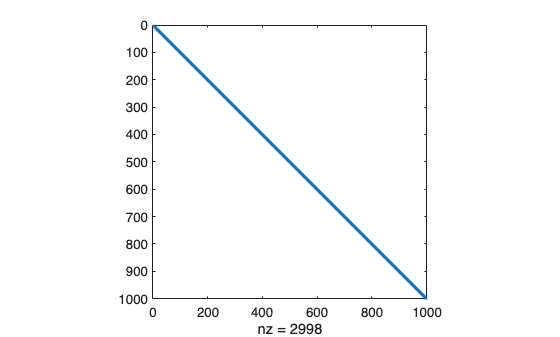

spy(As)

#### Reordering Functions

- `amd` Approximate minimum degree permutation

- `colamd` Column approximate minimum degree permutation

- `colperm` Sparse column permutation based on nonzero count

- `dmperm` Dulmage-Mendelsohn permutation/decomposition

- `randperm` Random permutation

- `symamd` Symmetric approximate minimum degreepermutation

- `symrcm` Sparse reverse Cuthill-McKee ordering

#### Sparse Matrix Tips

Don't change sparsity structure (pre-allocate)

- Do not want to dynamically grows triplet

- Each component of triplet must be stored contiguously

Accessing values (may be) slow in sparse storage as location of row/columns is not predictable

- If `S(i,j)` is requested, must search through row, col to find i, j

Component-wise indexing to assign values is expensive

- Requires accessing into an array

- If `S(i,j)` is previously zero, then `S(i,j)= c` changes sparsity structure

### Matrix Decompositions

#### Rank

[rank(rand(100,34)), rank(rand(100,1)*rand(1,34))]

ans =     34     1


#### Norms

a = rand(3,4);
norm(a,2) % 2-norm, default

ans = 1.8188

norm(a,1) % 1-norm

ans = 1.8704

norm(a,Inf) % infinity norm

ans = 2.8971

norm(a,'fro') % Frobenius norm

ans = 1.9676

Estimate matrix 2-norm for sparse matrices or large, full matrices

norm(Ad)

ans = 4.0000

normest(As,1e-4)

ans = 3.9633

#### Solve linear system $\textrm{Ax}=b$ by factorizing A.

- If A can be decomposed as $A=\textrm{BC}$, then the problem can be reduced to solving $\textrm{By}=b$ and $\textrm{Cx}=y$ where B and C are matrices such that these two systems are easy to solve.

- Examples of easy-to-solve matrices: diagonal, triangular, orthogonal

- For overdetermined system of equations, solve the linear least squares problem $\min \;\frac{1}{2}\left|\right|\textrm{Ax}-b\left|{\left|\right.}_2^2 \right.$

#### LU Decomposition

$A=\textrm{LU}$ where A is non-singular, L is lower-triangular, and U is upper triangular.

**Pivoting**

Gaussian elimination is unstable without pivoting:

- Partial pivoting: $\textrm{PA}=\textrm{LU}$

- Complete pivoting: $\textrm{PAQ}=\textrm{LU}$

**LU factorization, partial pivoting applied to L**

`[L,U] = lu(A)`

- $A=\left(P^{-1} \tilde{L} \right)U=\textrm{LU}$ where $\mathrm{U}$ upper tri, $\tilde{L}$ lower tri, $P$ row permutation

`Y = lu(A)`

- If A in sparse format, strict lower triangular of Y contains L and upper triangular contains U

- Permutation information lost

**LU factorization, partial pivoting P explicit**

`[L,U,P] = lu(A)`

- 
$$\textrm{PA}=\textrm{LU}$$


`[L,U,p] = lu(A,'vector')`

- 
$$A\left(p;:\right)=\textrm{LU}$$


**LU factorization, complete pivoting P,Q explicit**

`[L,U,P,Q] = lu(A)`

- 
$$\textrm{PAQ}=\textrm{LU}$$


`[L,U,p,q] = lu(A,'vector')`

- 
$$A\left(p;q\right)=\textrm{LU}$$


Additional `lu` call syntaxes that give

- Control over pivoting thresholds

- Scaling options

- Calls to UMFPACK vs LAPACK

#### Demo

load demo/matrix_lu.mat
A = sparse(linsys.row,linsys.col,linsys.val);
b = linsys.b;
clear linsys;

Compute LU decomposition and generate a spy plot of L and U

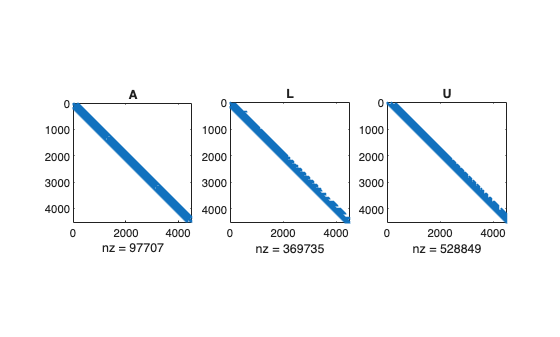

[L,U] = lu(A);
figure;
subplot(1,3,1); spy(A); title('A');
subplot(1,3,2); spy(L); title('L');
subplot(1,3,3); spy(U); title('U');

norm(A - L*U,'fro')

ans = 1.3525e-04

Compute LU decomposition with partial pivoting

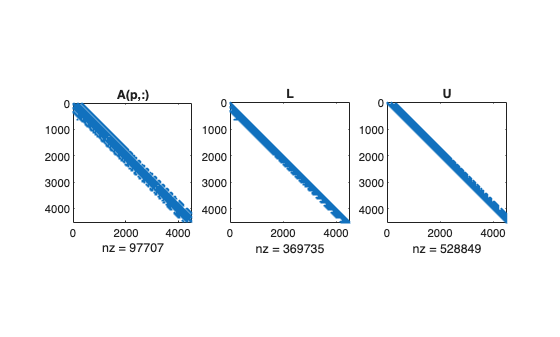

[L,U,p] = lu(A,'vector');
figure;
subplot(1,3,1); spy(A(p,:)); title('A(p,:)');
subplot(1,3,2); spy(L); title('L');
subplot(1,3,3); spy(U); title('U');

norm(A(p,:) - L*U,'fro')

ans = 1.3525e-04

Compute LU decomposition with complete pivoting

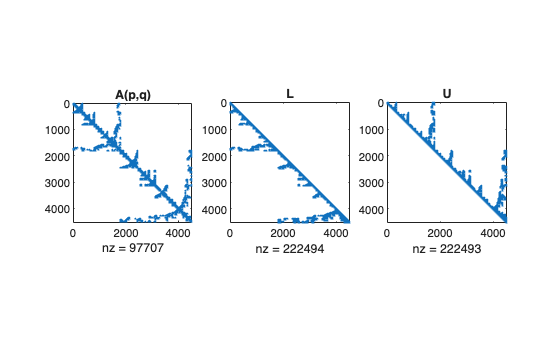

[L,U,p,q] = lu(A,'vector');
figure;
subplot(1,3,1); spy(A(p,q)); title('A(p,q)');
subplot(1,3,2); spy(L); title('L');
subplot(1,3,3); spy(U); title('U');

norm(A(p,q) - L*U,'fro')

ans = 8.8605e-05

#### Cholesky Factorization

$A=R^* R={\textrm{LL}}^*$ where $R$ is upper triangular and $\mathrm{L}$ is lower triangular.

- Cholesky Factorization is a variant of Gaussian elimination (LU) that operations on both left and right of the matrix simultaneously. 

- Every hermitian positive definite matrix A has a unique Cholesky factorization.

- Cholesky decomposition uses symmetric Gaussian elimination.

**symmetric, positive definite (SPD) matrix**

check SPD:

- A symmetric matrix A is SPD if and only if all its eigenvalues are positive $\to$ Eigenvalue decomposition *(expensive/difficult for large matrices)*

- If a Cholesky decomposition can be successfully computed, the matrix is SPD $\to$ Cholesky factorization *(best option)*

`R = chol(A)`

- Return error if A not SPD

`[R,p] = chol(A)`

- If A SPD, p = 0

- If A not SPD, returns Cholesky factorization of upper $p-1\times p-1$ block

`[R,p,S]=chol(A)`

- AMD preordering applied

- Attempt to maximize sparsity in factor

Sparse incomplete Cholesky (a sparse approximation of the Cholesky factorization): 

- `R =ichol(A,opts)`

Rank 1 update to Cholesky factorization: 

- `R1 = cholupdate(R, x)`

- Determine Cholesky factorization of rank 1 update $\tilde{R^T } \tilde{R} =A+{\textrm{xx}}^T$ using ${\textrm{RR}}^T =A$

#### Demo

Compute Cholesky decomposition of A

R = chol(A);

Compute Cholesky decomposition after reordering the matrix with approximate minimum degree permutation

p = amd(A); % approximate minimum degree permutation
Ramd = chol(A(p,p));

Compute incomplete Cholesky decomposition with `ichol` using drop tolerance of  0.01

% add alpha*diag(A) to make diagonally dominant matrix so 
% incomplete Cholesky is defined
alpha = max(sum(abs(A),2)./diag(A))-2;
Rinc = ichol(A, struct('type','ict','droptol',1e-2,'diagcomp',alpha, 'shape', 'upper'));

Generate spy plots

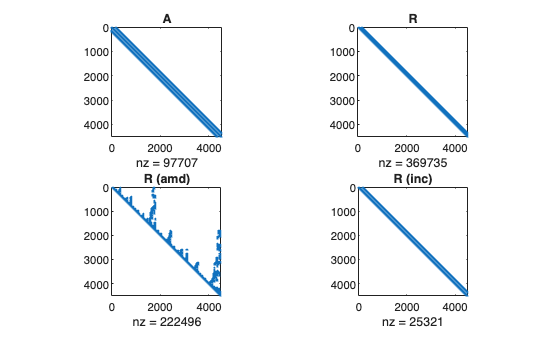

figure;
subplot(2,2,1); spy(A); title('A');
subplot(2,2,2); spy(R); title('R');
subplot(2,2,3); spy(Ramd); title('R (amd)');
subplot(2,2,4); spy(Rinc); title('R (inc)');

#### QR Factorization

$A=\textrm{QR}$ where $Q$ is orthogonal and $R$ is upper triangular.

Useful in:

- Pseudo-inverse

- Solution of least squares

- Solution of linear system of equations

- Extraction of orthogonal basis for column space of A

**For general matrix A (dense or sparse)**

Full QR factorization

- `[Q,R] = qr(A)`: $A=\textrm{QR}$

- `[Q,R,E] = qr(A)`: $\textrm{AE}=\textrm{QR}$

- Q: mxm, R: mxn, E: nxn permutation matric

Economy QR (skinny QR) factorization

- `[Q,R] = qr(A,0)`: $A=\textrm{QR}$

- `[Q,R,E] = qr(A,0)`: $A\left(:,E\right)=\textrm{QR}$

- Q: mxn, R: nxn, E: nx1 permutation matric

**For sparse matrix A**

Q-less QR factorization

- `R = qr(A), R = qr(A,0)`

Least-Squares: $\min \;\left|\right|\textrm{Ax}-b\left|\right|\Rightarrow x={\textrm{ER}}^{-1} C$

- `[C,R] = qr(A,B), [C,R,E] = qr(A,B), [C,R] = qr(A,B,0), [C,R,E] = qr(A,B,0)`

**Other QR algorithms**

QR of A with a column/row removed

- `[Q1,R1] = qrdelete(Q,R,j)`

- `[Q1,R1] = qrdelete(Q,R,j,'row')`

QR of A with vector x inserted as jth column/row

- `[Q1,R1] = qrinsert(Q,R,j,x)`

- `[Q1,R1] = qrinsert(Q,R,j,x,'row')`

#### Demo

Use QR to fit a polynomial


$$\(p(x) = a_m x^m + a_{m-1} x^{m-1} +... + a_1 x + a_0\).$$



$$\( \min ||Va -y ||_2 \)$$


$\(a = [a_m, ..., a_1, a_0], y = [y_1,..., y_n]\)$,$\(V_{i,j} = x_i^{m-j+1}\)$

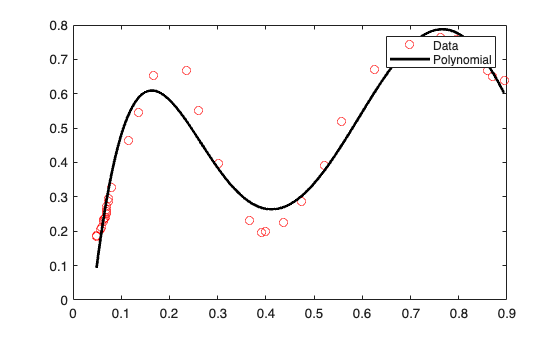

load('demo/regression_data.mat');
xfine = linspace(min(x),max(x),1000);
order = 5;

V = vander(x); % Vandermonde matrix
V = V(:,end-order:end);

[Q,R] = qr(V,0);
a = R \ (Q'*y);

figure;
plot(x,y,'ro'); hold on;
plot(xfine,polyval(a,xfine),'k-','linew',2);
legend('Data','Polynomial');

clear; clc

### Spectral Decompositions

#### Eigenvalue Decomposition (EVD)

$A=\textrm{XD}X^{-1}$ where A is diagonal matrix with the eigenvalues of A on the diagonal and the columns of X contain the eigenvectors of A.

- Diagonalizable (EVD exists) vs. defective (EVD does not exist)

- All EVD algorithms must be *iterative*

- Eigenvalue Decomposition algorithm: reduce to upper Hessenberg form and iteratively transform upper Hessenberg to upper triangular

**Compute eigenvalue decomposition** of $\textrm{AX}=\textrm{XD}$

Eigenvalues only: `d = eig(A)`

Eigenvalues and eigenvectors: `[X,D] = eig(A)`

`eig `also used to computed generalized EVD`: `$\textrm{Ax}=\lambda \textrm{Bx}$

- `E = eig(A,B) `- a column vector E containing the generalized eigenvalues

- `[V,D] = eig(A,B)`  - a diagonal matrix D of generalized eigenvalues and a full matrix V such that `A*V = B*V*D`

Use ARPACK to find largest eigenvalues and corresponding eigenvectors `(eigs)`

- By default returns 6 largest eigenvalues/eigenvectors

- `eigs(A,k), eigs(A,B,k)` for k largest eigenvalues/eigenvectors

- `eigs(A,k,sigma), eigs(A,B,k,sigma) `If `sigma` a number, e-vals closest to `sigma`

**Quiz**.

Consider the following matrix.

A = gallery('lehmer',4);

Find the eigenvalue decomposition of A. What is the largest eigenvalue?

Use the EVD to compute $A^3$. What is its matrix infinity norm? 

Use the EVD to compute $e^A$. What is its matrix one-norm?

#### Singular Value Decomposition

$A=U\Sigma V^T$ where $U$and $V$are orthogonal and $\Sigma$ is diagonal with real, positive entries.

SVD algorithm: bi-diagonalize A and iteratively transform bi-diagonal to diagonal

**Compute SVD**

Singular vales only: `s = svd(A)`

Full SVD: `[U,S,V] = svd(A)`

Reduced SVD

- `[U,S,V] = svd(A,0)`

- `[U,S,V] = svd(A,'econ')`

- Equivalent for $m\ge n$

`[U,V,X,C,S] = gsvd(A,B) `to compute generalized SVD

Use ARPACK to find largest singular values and corresponding singular vectors (`svds`)

- By default returns 6 largest singular values/vectors

- Same calling syntax as `eig` (or EVD and generalized EVD)

- `svds(A,k)` for k largest singular values/vectors

- `svds(A,k,sigma)`

### Direct Solvers


$$\textrm{Ax}=b$$


overdetermined, underdetermined, and determined


$$x=A^{-1} b$$


**forward and backward substitution**

`mldivide`** (**`\`**)**

load('demo/regression_data.mat');
xfine = linspace(min(x),max(x),1000);
order = 5;

V = vander(x); % Vandermonde matrix
V = V(:,end-order:end);
a = V \ y;

figure;
plot(x,y,'ro'); hold on;
plot(xfine,polyval(a,xfine),'k-','linew',2);
legend('Data','Polynomial');

Multiple right hand sides: `X = A\B`

Directly compute `inv(A)` is not using any of the fast, efficient, built-in MATLAB diagnostics that backslash is doing.

#### Condition Number $\kappa$

A matrix is well-conditioned for $\kappa$ close to 1; ill-conditioned for $\kappa$ large.

`cond`: returns 2-norm condition number

`condest`: lower bound for 1-norm condition number

`rcond`: LAPACK estimate of inverse of 1-norm condition number (estimate of $\left|\right|A^{-1} \left|{\left|\right.}_1 \right.$)

### Iterative Solvers

#### Preconditioning

Preconditioning replaces the original problem (Ax = b) with a different problems with the same (or similar) solution.

Left preconditioning: $L^{-1} \textrm{Ax}=L^{-1} b$

Right preconditioning: $y=\textrm{Rx},{\textrm{AR}}^{-1} y=b$

Left and right preconditioning: $L^{-1} {\textrm{AR}}^{-1} y=L^{-1} b$

**Preconditioner** `M `for A ideally provides a cheap approximation to $A^{-1}$, intended to drive condition number toward 1.

Typical preconditioners include

**Jacobi**:

- `M = diag(diag(A))`

- If $A_{\textrm{jj}}$ = 0, set $M_{\textrm{jj}}$ = 1

- Sparse storage (use `spdiags`)

**Incomplete factorizations**: LU, Cholesky, level of fill-in (beyond sparsity structure)

- `[L,U] = ilu(A,SETUP), [L,U,P] = ilu(A,SETUP): m`ost popular and cheapest: no fill-in, ILU(0) (`SETUP.TYPE='nofill'`)

- `R = ichol(X,opts): `default option for `type` is no fill

#### Common Iterative Solvers

Linear system of equations $\textrm{Ax}=b$

- Symmetric Positive Definite matrix: Conjugate Gradients (CG)

- Symmetric matrix: Symmetric LQ Method (SYMMLQ), Minimum-Residual (MINRES)

- General, Unsymmetric matrix: Biconjugate Gradients (BiCG), Biconjugate Gradients Stabilized (BiCGstab), Conjugate Gradients Squared (CGS), Generalized Minimum-Residual (GMRES)

Linear least-squares $\min \;\left|\right|\textrm{Ax}-b\left|{\left|\right.}_2 \right.$

- Least-Squares Minimum-Residual (LSMR)

- Least-Squares QR (LSQR)

#### MATLAB's built-in iterative solvers for $\textrm{Ax}=b,A\in R^{m\times m}$

`pcg, bicg, bicgstab, bicgstabl, cgs, minres, gmres, lsqr, qmr, symmlq, tmqmr`

**Call syntax** (similar for all)

`[x,flag,relres,iter,resvec] = solver(A,b,restart,tol,maxit,M1,M2,x0)`

Inputs (only A, b required, defaults for others):

- `A -` full or sparse (recommended) square matrix or function handle returning $\textrm{Av}$ for any $v\in R^m$

- `b - `m vector

- `restart -` restart frequency (GMRES)

- `tol -` relative convergence tolerance

- `maxit -` maximum number of iterations

- `M1, M2 -` full or sparse (recommended) preconditioner matrix or function handle returning $M_2^{-1} M_1^{-1} v$ for any $v\in R^m$ (can specify only M1 or no precondition system by not specifying `M1,M2` or setting `M1 = []` and `M2=[]`)

- `x0 -` initial guess at solution to $\textrm{Ax}=b$

Outputs:

- `x - `attempted solution to $\textrm{Ax}=b$

- `flag - `convergence flag

- `relres - `relative residual $\frac{\left|\right|b-\textrm{Ax}\left|\right|}{\left|\right|b\left|\right|}$ at convergence

- `iter - `number of iterations (inner and outer iterations for certain algorithms)

- `resvec - `vector of residual norms at each iteration $\left|\right|b-\textrm{Ax}\left|\right|$, including preconditioners if used ($\left|\right|M^{-1} \left(b-\textrm{Ax}\right)\left|\right|$)

#### Demo

close all; clear; clc

load demo/matrix_lu.mat
A = sparse(linsys.row,linsys.col,linsys.val);
b = linsys.b;
clear linsys;

%% CG, MINRES, GMRES
alpha = 2.5*1e-3;
Rinc = ichol(A, struct('type','ict','droptol',1e-3,'diagcomp',alpha, 'shape', 'upper'));

% Get exact solution using backslash
x = A \ b;
chol(A);

% Use PCG to solve Ax = b (precondition with Rinc)
[x_pcg,flag_pcg,relres_pcg,iter_pcg,resvec_pcg] = pcg(A,b,1e-6,1000,@(x) Rinc\(Rinc'\x));
% Use MINRES to solve Ax = b (precondition with Rinc)
[x_mnr,flag_mnr,relres_mnr,iter_mnr,resvec_mnr] = minres(A,b,1e-6,1000,@(x) Rinc\(Rinc'\x));
% Use GMRES to solve Ax = b (precondition with Rinc)
[x_gmr,flag_gmr,relres_gmr,iter_gmr,resvec_gmr] = gmres(A,b,[],1e-9,1000,@(x) Rinc\(Rinc'\x));

fprintf('Error, iter PCG    = %e, %d\n',norm(x - x_pcg),iter_pcg);

Error, iter PCG    = 5.008013e-12, 130


fprintf('Error, iter MINRES = %e, %d\n',norm(x - x_mnr),iter_mnr);

Error, iter MINRES = 5.919403e-12, 130


fprintf('Error, iter GMRES  = %e, %d\n',norm(x - x_gmr),prod(iter_gmr));

Error, iter GMRES  = 6.500756e-14, 139


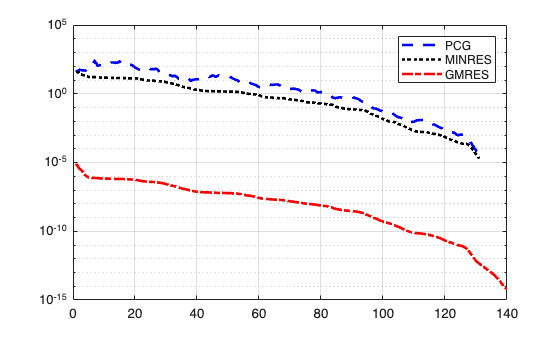

figure
plot(resvec_pcg,'b--','linew',2); hold on;
plot(resvec_mnr,'k:','linew',2);
plot(resvec_gmr,'r-.','linew',2); grid on;
legend('PCG','MINRES','GMRES');
set(gca,'yscale','log');

addpath(pwd);
MATFILE = "ns2d_pretrained_outputs/ns2d_fno_pretrained_export.mat";

function [U, mask, x, y] = flowbench_extract_velocity_xy(S, sample_for_mask)

    if nargin < 2, sample_for_mask = 1; end

    X = S.X_data;
    Y = S.Y_data;

    Ns = size(Y,1);
    Ny = size(Y,3);
    Nx = size(Y,4);

    U.u = permute(squeeze(Y(:,1,:,:)), [2 3 1]);% Ny x Nx x Ns
    U.v = permute(squeeze(Y(:,2,:,:)), [2 3 1]);% Ny x Nx x Ns

    if isfield(S,"mask")
        mask = logical(squeeze(S.mask));
        if ~isequal(size(mask), [Ny, Nx])
            mask = true(Ny, Nx);
        end
    else
        mask = true(Ny, Nx);
    end
    
    if isfield(S,"x"), x = S.x(:)'; else, x = linspace(0,1,Nx); end
    if isfield(S,"y"), y = S.y(:)'; else, y = linspace(0,1,Ny); end
end

## NLA Demo 1: POD / SVD compression of velocity fields (data matrix viewpoint)

This demo leverages what we saw earlier with SVD and low-rank approximation: a stack of flow snapshots is turned into a single matrix whose columns are vectorized states. 

The goal is to identify a small set of dominant spatial modes that efficiently represent an entire time-evolving flow, and to quantify how much information is lost as we restrict ourselves to them. In practice, this is a controlled experiment in data compression and model reduction: we ask how many degrees of freedom are truly needed to capture the essential physics of the velocity field.

A common technique called Proper Orthogonal Decomposition (**POD**) is, in practice, nothing more than the **SVD** of this snapshot matrix. The value pedagogically is that *“low rank” stops being abstract*: it becomes a quantitative statement about how many modes are needed to approximate a family of physically related fields.

**What to think about:**

- SVD as an optimal low-rank approximation (in Frobenius norm).

- Interpreting singular values as an energy/variance spectrum of the data matrix.

- Rank–error tradeoff curves as a practical compression diagnostic.

**What to expect:**

- A decaying singular value spectrum: fast decay indicates strong low-dimensional structure (dominant coherent patterns); slow decay indicates richer dynamics and weaker compressibility.

- The reconstruction error $\|X-X_r\|_F / \| X \|_F$ should decrease monotonically with $r$. In many fluid datasets, the first few modes capture the large-scale circulation and shear; additional modes mop up smaller structures.

- If the mask removes solid regions, the “data matrix” is effectively built on an irregular domain; the SVD still behaves cleanly, but the modes should be interpreted as basis functions on the *fluid* region only.`

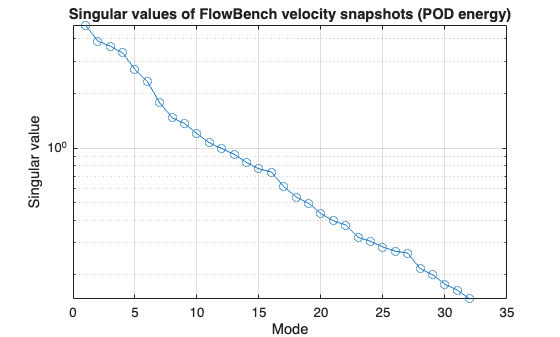

S = load(MATFILE);
[U, mask, x, y] = flowbench_extract_velocity_xy(S);
u = U.u;
v = U.v;

Ny = size(u,1); Nx = size(u,2); Ns = size(u,3);

idx = find(mask(:));
Xsnap = zeros(2*numel(idx), Ns);
for k = 1:Ns
    uk = u(:,:,k); vk = v(:,:,k);
    Xsnap(:,k) = [uk(idx); vk(idx)];
end

[Phi, Sigma, W] = svd(Xsnap, "econ");
s = diag(Sigma);

figure; semilogy(s, "o-"); grid on
title("Singular values of FlowBench velocity snapshots (POD energy)")
xlabel("Mode"); ylabel("Singular value")

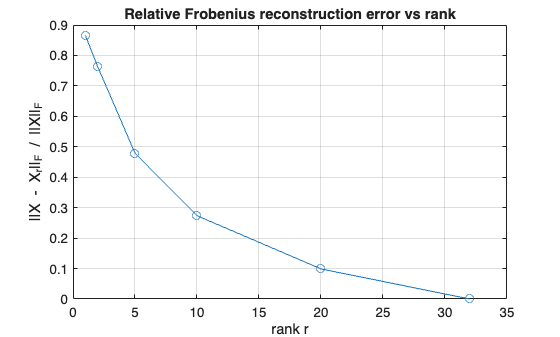

% Reconstruction error vs rank r
rList = [1 2 5 10 20 32];
err = zeros(size(rList));
for i = 1:numel(rList)
    r = rList(i);
    Xr = Phi(:,1:r) * Sigma(1:r,1:r) * W(:,1:r)';
    err(i) = norm(Xsnap - Xr, "fro") / norm(Xsnap, "fro");
end

figure; plot(rList, err, "o-"); grid on
title("Relative Frobenius reconstruction error vs rank")
xlabel("rank r"); ylabel("||X - X_r||_F / ||X||_F")

## NLA Demo 2 — Sparse matrices + Poisson solve (direct vs iterative)

In this demo, we recover a streamfunction from a vorticity field and show why solver choice (direct vs iterative) matters for sparse linear systems. 

The code works as follows:

- Load one 2D velocity snapshot and set up the grid.

- Read the vorticity field from the data and plot speed and vorticity for a quick sanity check.

- Mark the interior fluid grid points as unknowns and enforce zero values on the outer boundary (and outside the mask).

- Build a sparse finite-difference matrix that represents the negative Laplacian operator on the unknown points.

- Form the right-hand side from the vorticity values on those unknown points.

- Solve the sparse linear system in two ways: a direct factorization and an iterative method (PCG) with an incomplete Cholesky preconditioner.

- Put the solution back on the grid and plot contours of the streamfunction, which act like streamlines.

S = load(MATFILE);

Y = S.Y_data;
Ns = size(Y,1);
Ny = size(Y,3);
Nx = size(Y,4);

k = min(1, Ns);
u = squeeze(Y(k,1,:,:));
v = squeeze(Y(k,2,:,:));

fprintf("u size = %s\n", mat2str(size(u)));

u size = [128 128]


fprintf("v size = %s\n", mat2str(size(v)));

v size = [128 128]


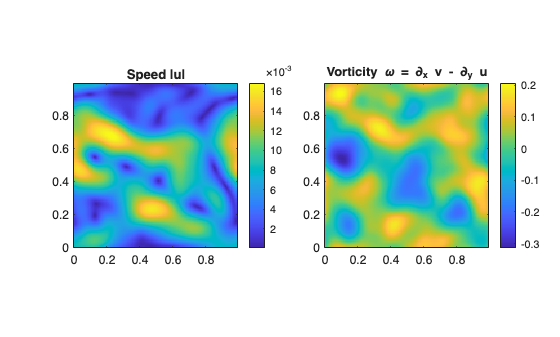

if isfield(S,"x"), x = S.x(:)'; else, x = linspace(0,1,Nx); end
if isfield(S,"y"), y = S.y(:)'; else, y = linspace(0,1,Ny); end

hx = x(2) - x(1);
hy = y(2) - y(1);

if isfield(S,"mask")
    mask = logical(squeeze(S.mask));
else
    mask = true(Ny, Nx);
end

omega = squeeze(Y(k,3,:,:));
omega(~mask) = 0;

figure;
tiledlayout(1,2);
nexttile;
imagesc(x, y, hypot(u,v).*mask); set(gca,"YDir","normal"); axis image; colorbar
title("Speed |u|");
nexttile;
imagesc(x, y, omega.*mask); set(gca,"YDir","normal"); axis image; colorbar
title("Vorticity \omega = \partial_x v - \partial_y u");


% Build sparse FD matrix for (-Laplace) on the unknown nodes (Dirichlet boundaries)
% We solve: (-Delta) phi = omega on interior fluid nodes
% with phi = 0 on boundaries and on masked-out nodes.

unknown = mask;
unknown(1,:)   = false;
unknown(end,:) = false;
unknown(:,1)   = false;
unknown(:,end) = false;

id = zeros(Ny, Nx);
id(unknown) = 1:nnz(unknown);
n = nnz(unknown);

% Preallocate ~5 entries per row (center + 4 neighbors)
I = zeros(5*n,1);
J = zeros(5*n,1);
Vv = zeros(5*n,1);
ptr = 0;

cx = 1/hx^2;
cy = 1/hy^2;

for ii = 2:Ny-1
    for jj = 2:Nx-1
        if ~unknown(ii,jj), continue; end
        row = id(ii,jj);

        % center
        ptr = ptr + 1;
        I(ptr) = row; J(ptr) = row; Vv(ptr) = 2*cx + 2*cy;

        % left
        if unknown(ii, jj-1)
            ptr = ptr + 1;
            I(ptr) = row; J(ptr) = id(ii, jj-1); Vv(ptr) = -cx;
        end
        % right
        if unknown(ii, jj+1)
            ptr = ptr + 1;
            I(ptr) = row; J(ptr) = id(ii, jj+1); Vv(ptr) = -cx;
        end
        % down (ii-1)
        if unknown(ii-1, jj)
            ptr = ptr + 1;
            I(ptr) = row; J(ptr) = id(ii-1, jj); Vv(ptr) = -cy;
        end
        % up (ii+1)
        if unknown(ii+1, jj)
            ptr = ptr + 1;
            I(ptr) = row; J(ptr) = id(ii+1, jj); Vv(ptr) = -cy;
        end
    end
end

I = I(1:ptr); J = J(1:ptr); Vv = Vv(1:ptr);
A = sparse(I, J, Vv, n, n);

b = omega(unknown);

figure; spy(A); title("Sparsity pattern of A = (-\Delta) on unknown nodes");

%Solve with (a) direct and (b) PCG+ICHOL
% (a) Direct (Cholesky)
t_direct = NaN;
psi_direct = [];

tic;
dA = decomposition(A, "chol");
psi_direct = dA \ b;
t_direct = toc;

% (b) Iterative PCG with incomplete Cholesky preconditioner
setup.type   = "ict";
setup.droptol = 1e-3;

tic;
M = ichol(A, setup);
t_precond = toc;

tol = 1e-8;
maxit = 400;

tic;
[psi_pcg, flag, relres, it] = pcg(A, b, tol, maxit, M, M');

t_pcg = toc;

fprintf("\n--- Solve timings ---\n");


--- Solve timings ---


fprintf("Direct solve time: %.3f s\n", t_direct);

Direct solve time: 0.019 s


fprintf("ICHOL build time:  %.3f s\n", t_precond);

ICHOL build time:  0.004 s


fprintf("PCG solve time:    %.3f s (flag=%d, relres=%.2e, it=%d)\n", t_pcg, flag, relres, it);

PCG solve time:    0.042 s (flag=3, relres=7.16e-05, it=25)



% Put solution back onto grid + visualize streamfunction and streamlines
psi_grid = zeros(Ny, Nx);
psi_grid(unknown) = psi_pcg;

figure;
contourf(x, y, psi_grid, 35, "LineColor", "none");
set(gca,"YDir","normal"); axis image; colorbar
title("Streamfunction \psi from FlowBench vorticity (solve (-\Delta)\psi = \omega)");

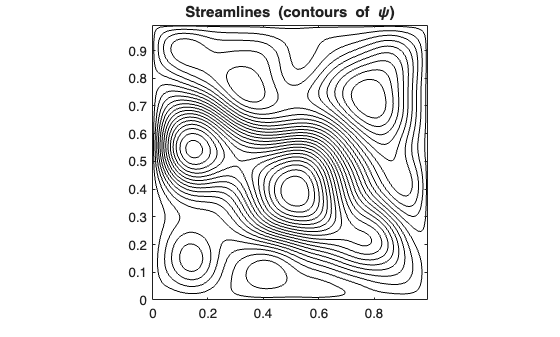

figure;
contour(x, y, psi_grid, 25, "k");
set(gca,"YDir","normal"); axis image
title("Streamlines (contours of \psi)");

% Residual check
res = norm(A*psi_pcg - b) / norm(b);
fprintf("Relative residual ||A psi - b|| / ||b|| = %.2e\n", res);

Relative residual ||A psi - b|| / ||b|| = 7.16e-05


## NLA Demo 3: Least squares + conditioning

In this last demo, we fit a polynomial in two ways and demonstrate how choosing the correct NLA technique can be valuable in your workflows. 

The code works as follows: 

- Load in the 2D scalar field u and determine your grid (x, y). 

- Take a single “vertical slice” through the middle which will form a smooth curve

- Fit that 1D curve with a degree-12 polynomial: p(y) = \sum c_k y^k

- This fits a matrix A where each column is y^j and is called a vandermonde matrix. A_jk = y_j^k

- We want to find coefficients c such that Ac approximately equals u

-  This is found via least squares typically: c = argmin( ||Ac - u||_2^2)

- Solve the fiting problem in two ways: QR and normal equations

S = load(MATFILE);

Y = S.Y_data;
Ns = size(Y,1);
Ny = size(Y,3);
Nx = size(Y,4);

k = 1;

u = squeeze(Y(k,1,:,:));

if isfield(S,"x"), x = S.x(:)'; else, x = linspace(0,1,Nx); end
if isfield(S,"y"), y = S.y(:)'; else, y = linspace(0,1,Ny); end
if isfield(S,"mask")
    mask = logical(squeeze(S.mask));
else
    mask = true(Ny, Nx);
end

ix = round(Nx/2);
yy = y(:);
uu = u(:, ix);
fluidSlice = mask(:, ix);

yy = yy(fluidSlice);
uu = uu(fluidSlice);


%% Build polynomial Vandermonde matrix
deg = 12;
A = zeros(numel(yy), deg+1);
for j = 0:deg
    A(:, j+1) = yy.^j;
end

fprintf("cond(A) ~ %.2e (Vandermonde grows ill-conditioned with degree)\n", cond(A));

cond(A) ~ 2.84e+08 (Vandermonde grows ill-conditioned with degree)



%% Solve least squares using QR (stable)
[Q,R] = qr(A, 0);
c_qr = R \ (Q' * uu);

%% Solve using normal equations (often less stable)
c_ne = (A' * A) \ (A' * uu);

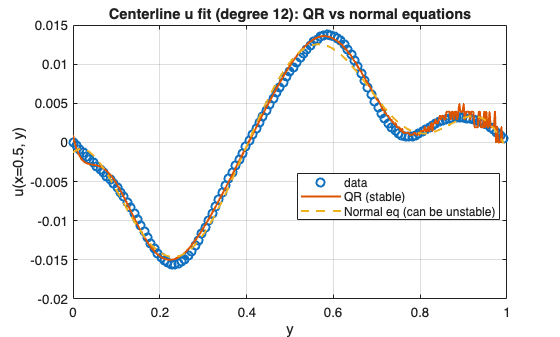

% Plot fits
yyFine = linspace(min(yy), max(yy), 400)';
AFine = zeros(numel(yyFine), deg+1);
for j = 0:deg
    AFine(:, j+1) = yyFine.^j;
end

fit_qr = AFine * c_qr;
fit_ne = AFine * c_ne;

figure;
plot(yy, uu, "o", yyFine, fit_qr, "-", yyFine, fit_ne, "--", "LineWidth", 1.5);
grid on;
xlabel("y"); ylabel("u(x=0.5, y)");
title(sprintf("Centerline u fit (degree %d): QR vs normal equations", deg));
legend("data", "QR (stable)", "Normal eq (can be unstable)", "Location", "best");

% Quantify fit error on the observed points
uu_qr = A * c_qr;
uu_ne = A * c_ne;

relerr_qr = norm(uu - uu_qr) / norm(uu);
relerr_ne = norm(uu - uu_ne) / norm(uu);

fprintf("Relative fit error (on slice points): QR=%.3e, NormalEq=%.3e\n", relerr_qr, relerr_ne);

Relative fit error (on slice points): QR=8.073e-02, NormalEq=1.050e-01


# In-Class Examples

## Sparse vs. Dense Memory Requirements

n = 1000;
% Dense matrix
A = zeros(n,n);
A(1:n+1:end) = 2;
A(2:n+1:end) = -1;
A(n+1:n+1:end) = -1;
printmat(A(1:10, 1:10))

 
                    --1-->       --2-->       --3-->       --4-->       --5-->
       --1-->      2.00000     -1.00000            0            0            0
       --2-->     -1.00000      2.00000     -1.00000            0            0
       --3-->            0     -1.00000      2.00000     -1.00000            0
       --4-->            0            0     -1.00000      2.00000     -1.00000
       --5-->            0            0            0     -1.00000      2.00000
       --6-->            0            0            0            0     -1.00000
       --7-->            0            0            0            0            0
       --8-->            0            0            0            0            0
       --9-->            0            0            0            0            0
      --10-->            0            0            0            0            0
 
                    --6-->       --7-->       --8-->       --9-->      --10-->
       --1-->            0            0         

% Triplet form
I = [ (1:n)';     (1:n-1)';   (2:n)'   ];
J = [ (1:n)';     (2:n)';     (1:n-1)' ];
V = [ 2*ones(n,1); -ones(n-1,1); -ones(n-1,1) ];

% Sparse matrix from triplets
S = sparse(I,J,V,n,n);

% Memory usage
whos A S I J V

  Name         Size                Bytes  Class     Attributes

  A         1000x1000            8000000  double              
  I         2998x1                 23984  double              
  J         2998x1                 23984  double              
  S         1000x1000              55976  double    sparse    
  V         2998x1                 23984  double              



## Sparse vs Dense Timing Example

n = 5000; e = ones(n,1);
A_dense  = diag(-2*e) + diag(e(1:end-1),1) + diag(e(1:end-1),-1);
A_sparse = spdiags([e -2*e e], -1:1, n, n);
b = ones(n,1);
t_dense  = timeit(@() A_dense\b);
t_sparse = timeit(@() A_sparse\b);
[t_dense, t_sparse]

ans =     0.0113    0.0001


## Sparse Matrix Reordering

S = sprandsym(2500, 0.002, 1e-2, 1);
p1 = colperm(S);
p2 = amd(S);
R0 = chol(S);
R1 = chol(S(p1,p1));
R2 = chol(S(p2,p2));
[nnz(R0), nnz(R1), nnz(R2)]

ans =        20292        7559        7263


## Least-squares via QR / backslash

% Fit y ≈ c1*x + c0
x = (0:0.1:1)';
A = [x ones(size(x))];
b = sin(2*pi*x);

% Least-squares solution
c = A\b;
c

c =    -1.3989
    0.6995



% Explicit QR route
[Q,R] = qr(A,0);
c_qr = R\(Q'*b);
c_qr

c_qr =    -1.3989
    0.6995


## Condition Number Sensitivity

A = hilb(10);
b = ones(10,1);
x = A\b;

condA = cond(A);

db = 1e-8 * randn(size(b));
x2 = A\(b + db);

rel_b = norm(db)/norm(b);
rel_x = norm(x2 - x)/norm(x);

fprintf('Condition number of A: %.2e\n', condA);

Condition number of A: 1.60e+13


fprintf('Relative perturbation in b: %.2e\n', rel_b);

Relative perturbation in b: 1.08e-08


fprintf('Relative change in solution: %.2e\n', rel_x);

Relative change in solution: 3.19e-04


fprintf('Amplification factor (~cond): %.2e\n', rel_x / rel_b);

Amplification factor (~cond): 2.95e+04


## Preconditioned CG (pcg) in MATLAB

n = 1000;
m = round(sqrt(n)) + 2;
A = delsq(numgrid('S', m));
b = ones(size(A,1),1);
L = ichol(A, struct('diagcomp',1e-2));
[x,flag,relres,iter,resvec] = pcg(A,b,1e-8,200,L,L');
fprintf('size(A)=%d, condest(A)=%.2e\n', size(A,1), condest(A));

size(A)=1024, condest(A)=6.40e+02


fprintf('pcg: flag=%d, iter=%d, relres=%.2e\n', flag, iter, relres);

pcg: flag=0, iter=30, relres=3.82e-09


## Symbolic Math Example 1

syms x a b positive real

I = int(exp(-a*x^2)*cos(b*x), x, 0, inf);
I_simplified = simplify(I);

disp('Integral result:')

Integral result:


pretty(I_simplified)

            /     2 \
            |    b  |
sqrt(pi) exp| - --- |
            \   4 a /
---------------------
      2 sqrt(a)




a_val = 2; b_val = 3;
I_num_sym = double(subs(I_simplified, [a b], [a_val b_val]));
I_num_quad = integral(@(t) exp(-a_val*t.^2).*cos(b_val*t), 0, Inf);

fprintf('Symbolic: %.15f\n', I_num_sym);

Symbolic: 0.203445763527289


fprintf('Numeric : %.15f\n', I_num_quad);

Numeric : 0.203445763527288


fprintf('Abs diff: %.3e\n', abs(I_num_sym - I_num_quad));

Abs diff: 1.027e-15


## Symbolic Math Example 2

syms x s real
assumeAlso(s > 0 & s < 1)

I = int(x^(s-1)/(1+x), x, 0, inf);
I_simplified = simplify(I);

disp('Integral result:')

Integral result:


pretty(I_simplified)

    pi
---------
sin(pi s)




s_val = 0.37;
I_num_sym = double(subs(I_simplified, s, s_val));
I_num_quad = integral(@(t) t.^(s_val-1)./(1+t), 0, Inf);

fprintf('Symbolic: %.15f\n', I_num_sym);

Symbolic: 3.423129195615263


fprintf('Numeric : %.15f\n', I_num_quad);

Numeric : 3.423128249625757


fprintf('Abs diff: %.3e\n', abs(I_num_sym - I_num_quad));

Abs diff: 9.460e-07
